% Pressure Drop Calculator for Phoenix Ethanol Line
%{
Made by Eric Miranda

The purpose of this MATLAB script is to estimate the pressure drop
experienced in the feed line of Phoenix.
Good resources for learning how to calculate pressure drop are Fluid
Mechanics by Frank M. White, and Crane Technical Paper 410. Both of these
are in the sharepoint under Documents\02 - Liquid Projects\ 94 - Phoenix\
Feed System\Educational Resources.
%}

clear
clc

addpath("Pressure_Drop_Functions\")


%% Variables
% These are the variables needed to make the pressure drop calculations

% Constants
g = 9.807; %m/s^2
fluid = "Nitrous"

fluid = "Nitrous"

temp_unit = "Farenheight"

temp_unit = "Farenheight"

temperature = 65

temperature = 65

if strcmp(temp_unit, 'Celsius')
    temperature = temperature * 1.8 + 32;
end
[density, viscosity] = getProperties(fluid, temperature)

density = 797.5500

viscosity = 0.0702

viscosity = viscosity / 1000;
% Inputs
ID_in = 0.5; %in
Mass_FR_in = 3.157; %lbm/s
Length_pipe_in = 18; %in  This is the TOTAL length of the ethanol line
roughness = 0.000002; %m From pg 371 in Fluid Mechanics 7th ed by Frank M. White
z_change_in = 18; %in, height change from the fuel bulkhead outlet to injector inlet

%Calculated Properties
ID = ID_in *.0254; %m
Length_pipe = Length_pipe_in * .0254; %m
Mass_FR = Mass_FR_in * 0.45359237; %kg/s
Volume_FR = Mass_FR / density; %m^3/s
V_avg = Volume_FR/(pi*ID^2/4); %m/s
Re_d = density * V_avg * ID / viscosity; % Reynolds number
fprintf('Reynold''s number: %f\n', Re_d)

Reynold's number: 2044581.607615


Relative_Roughness = roughness / ID;
fprintf('Relative roughness: %f\n', Relative_Roughness)

Relative roughness: 0.000157


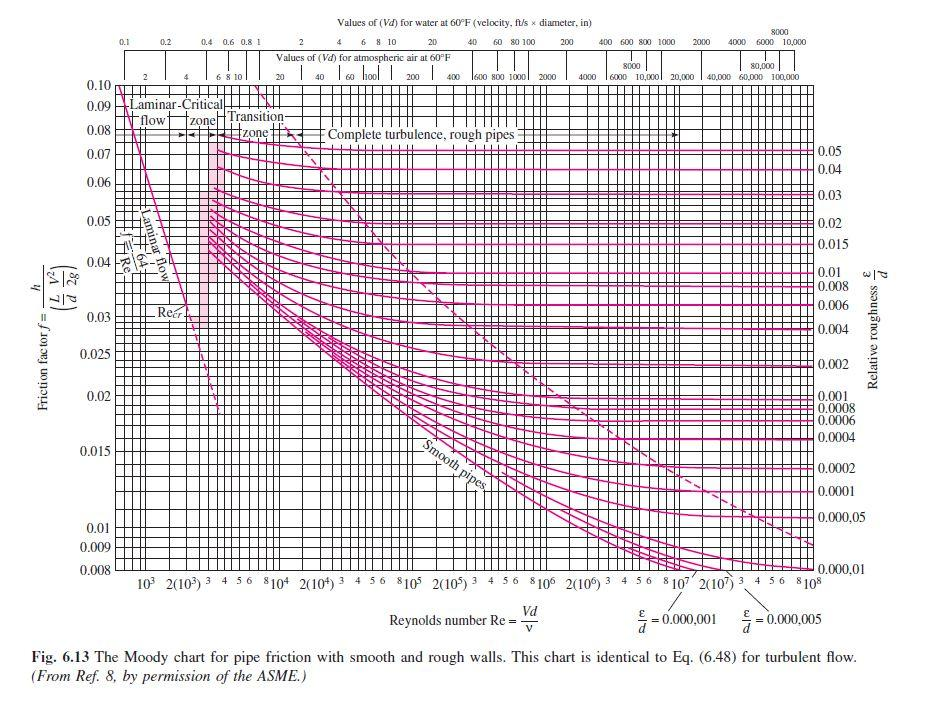

Friction_Factor = 0.014; % From Moody chart using calculated Reynolds number and relative roughness values
z_change = z_change_in * .0254; %m

%% Head Loss Calculations
% This section is for calculating the head loss in the ethanol pipe from friction
% and fittings before it reaches the injector.

% Major Loss
h_f = majorloss(Friction_Factor, Length_pipe, ID, V_avg, g); %m

% Minor Losses
valve_type = "1/2";

K_entrance = .42*(1-.547^2/5.75^2); % Sudden contraction from tank to tube using .547 in as ID of ORB fitting and 5.75 in as tank ID
K_elbow = 2.0; % From pg 391 in Fluid Mechanics 7th ed by Frank M. White
elbow_num = 0; % Number of 90 degree turns
K_tee = .9; % See K_elbow source
tee_num = 1

tee_num = 1


if valve_type == "1/2"
    K_valve = .3; % Extremely conservative estimate
    K_tot = K_entrance + K_elbow * elbow_num + K_valve + K_tee;
    h_m = minorloss(K_tot, V_avg, g);
elseif valve_type == "1/4"
    % 1/4 ball valve
    K_1valve4 = 1.364; % Calculated using C_v = 29.9*d^2/sqrt(K)
    K_1contraction4 = .42*(1-.25^2/ID_in^2);
    K_1expansion4 = (1-.25^2/ID_in^2)^2;
    K_tot = K_entrance + K_elbow * elbow_num + K_tee + K_1contraction4;
    h_m = minorloss(K_tot, V_avg, g);
    h_m = h_m + minorloss(K_1valve4 + K_1expansion4, V_avg*(ID_in/.25)^2, g);
end

%% Pressure Drop Calculation
% This segment of the code translates the head loss calculated in the
% previous section to pressure drop experienced in the ethanol line before
% reaching the injector.

Pressure_drop = hloss2pdrop(h_f, h_m, z_change, density, g); %Pa
Pressure_drop_psi = Pressure_drop * 0.0001450377; %psi
Pressure_drop_bar = Pressure_drop / 1e5; %Bar

%% Output
% This section outputs the pressure drop cleanly in the command window.

fprintf('Pressure Drop:\n%.2f Pa\n%.2f psi\n%.2f Bar\n', Pressure_drop, Pressure_drop_psi, Pressure_drop_bar)

Pressure Drop:
166277.57 Pa
24.12 psi
1.66 Bar
